Demo code for Figure 5 of Idesis (2022) - Edge centric analysis of stroke patients. An alternative approach for biomarkers of lesion recovery

Edge-centric code adapted from Faskowitz, J. et al (2020) and Zamani Esfahalani (2020)

(https://github.com/brain-networks)

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything
nodes = 200; % Amount of nodes from the dataset

Add helper functions and data to path

addpath('Functions');
addpath('Data');

Load regional time series

load data/ts.mat %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)

Create fake data of 5 stroke patients

amount_of_patients= 5; %Number for demo
for subj = 1:amount_of_patients
    ts_patients(:,:,subj)= ts.*(randn(1200,200)*4); %original ts plus a bigger factor random amount to make every subject different
end

High amplitude - Patients

for subj = 1:size(ts_patients,3)
    ts = ts_patients(:,:,subj);
    ts = zscore(ts); % z-score time series
    [ntime,nnodes] = size(ts); % get dimensions
    nedges = nnodes*(nnodes - 1)/2; % calculate number of edges
    [u,v] = find(triu(ones(nnodes),1)); % indices of unique edges (upper triangle)
    idx = (v - 1)*nnodes + u;
    fc = corr(ts); %% calculate static fc
    ets = ts(:,u).*ts(:,v); %% generate edge time series
    fc_upper_triangle = fc(idx);
    rms = sum(ets.^2,2).^0.5; % calculate co-fluctuation amplitude at each frame
    frackeep = 0.1; % fraction of high- and low-amplitude frames to retain
    nkeep = round(ntime*frackeep);
    [~,idxsort] = sort(rms,'descend'); % sort co-fluctuation amplitude
    fctop = corr(ts(idxsort(1:nkeep),:)); % estimate fc using just high-amplitude frames
    fcbot = corr(ts(idxsort(end - nkeep + 1:end),:)); % do the same using just low-amplitude
    corr_top_patients(subj)=corr(fctop(idx),fc(idx)); %correlation of top 10% with the whole FC matrix
    corr_bot_patients(subj)=corr(fcbot(idx),fc(idx)); %correlation of bottom 10% with the whole FC matrix
    %% calculate modularity of high-/low-amplitude fc
    numiter = 100; 
    qtop = zeros(numiter,1); qbot = qtop;
    for iter = 1:numiter
       [~,qtop(iter)] = community_louvain(fctop,[],[],'negative_asym');
       [~,qbot(iter)] = community_louvain(fcbot,[],[],'negative_asym');
    end
    qtop_3d(subj,:) = qtop;
    qbot_3d(subj,:) = qbot;
    %fprintf('Subject: %d done\n',i) %Uncomment if there are many subjects
    %in order to keep track of progress
end


Calculate regression of lesion volume and Domains recovered

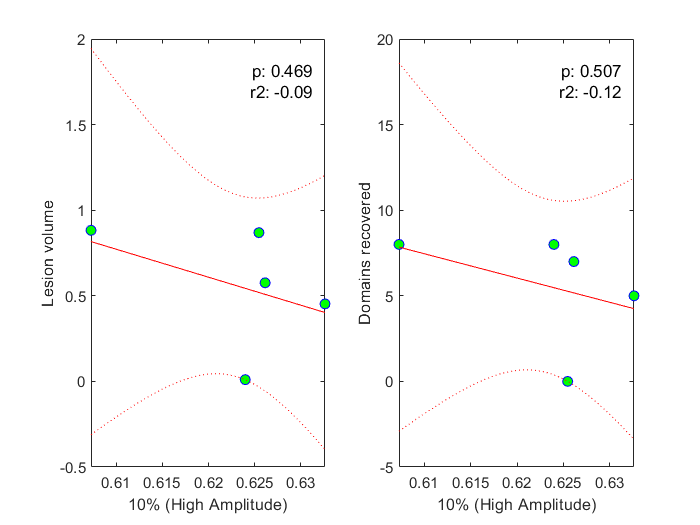

lesion_volume=rand(1,length(corr_top_patients));
domains_recovered=randi([0 9],1,length(corr_top_patients));

figure()
subplot(121)
mdlr = fitlm(corr_top_patients,lesion_volume);
regr_plot=plot(mdlr);
legend('off')
xlabel('10% (High Amplitude)');
ylabel('Lesion volume')
set(regr_plot(1),'Marker','o')
set(regr_plot(1),'MarkerFaceColor','g')
r2 = mdlr.Rsquared.Adjusted;
p = coefTest(mdlr);
p_plot = round(p,3);
r2_plot = round(r2,2);
NE = [max(xlim) max(ylim)]-[diff(xlim) diff(ylim)]*0.05;
txt = ['p: ' num2str(p_plot) newline 'r2: ' num2str(r2_plot)];
text(NE(1), NE(2), txt, 'VerticalAlignment','top', 'HorizontalAlignment','right')
title('')

subplot(122)
mdlr = fitlm(corr_top_patients,domains_recovered);
regr_plot=plot(mdlr);
legend('off')
xlabel('10% (High Amplitude)');
ylabel('Domains recovered')
set(regr_plot(1),'Marker','o')
set(regr_plot(1),'MarkerFaceColor','g')
r2 = mdlr.Rsquared.Adjusted;
p = coefTest(mdlr);
p_plot = round(p,3);
r2_plot = round(r2,2);
NE = [max(xlim) max(ylim)]-[diff(xlim) diff(ylim)]*0.05;
txt = ['p: ' num2str(p_plot) newline 'r2: ' num2str(r2_plot)];
text(NE(1), NE(2), txt, 'VerticalAlignment','top', 'HorizontalAlignment','right')
title('')

Compare highest and lowest decile

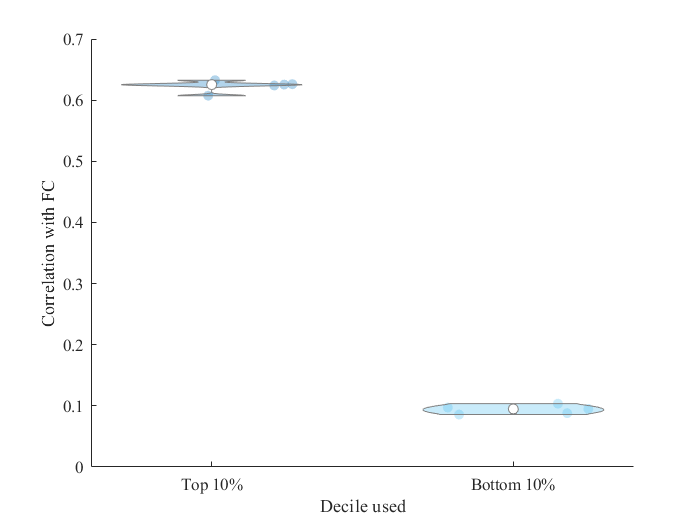

temp_combined = [corr_top_patients,...
                 corr_bot_patients];
group = [zeros(1,length(corr_top_patients)),...
        (ones(1,length(corr_bot_patients))*1)];
figure()
vs = violinplot(temp_combined, group);        
xticklabels({'Top 10%','Bottom 10%'})
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',10)
ylabel('Correlation with FC')
xlabel('Decile used')

Visualize top 10% vs bottom 10% FC

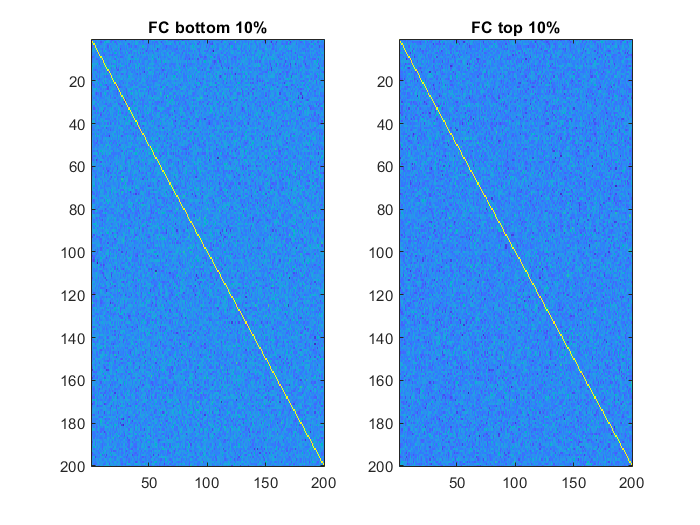

figure()
subplot(121)
imagesc(fcbot);title('FC bottom 10%');
subplot(122)
imagesc(fctop);title('FC top 10%');